# The Impacts of Energy Production on Temperature and Carbon Dioxide

## Summary:

In the past couple of years, there has been an emphasis placed on climate change, more specifically how the usage of nonrenewable energy affects it. Although using fossil fuels for energy is cheaper and easier than the more sustainable options, it is detrimental to the environment. Upon the realization that if we continue depending on fossil fuels, there will be irreversible damage done to the environment, the usage of renewable energy has increased. When looking at data published by the U.S. Energy Information Administration, it can be seen that in the timespan between 1950 and 2019 primary energy consumptions have tripled. Similarly, within the same timeframe, carbon dioxide emissions have doubled. However, by taking a closer look at the data, it is clear that the increase is not linear. Based on the data included in “Table 1.7 Primary Energy Consumption, Energy Expenditures, and Carbon Dioxide Emissions Indicators” it can be noted that both the primary energy consumptions and the carbon dioxide emissions have increased from 1950 to around 2002. However, after 2002, the data plateaus, depicting an effort by the United States to mitigate climate change by decreasing the usage of fossil fuels. Similarly, when looking at the data included in “Table 10.1 Renewable Energy Production and Consumption by Source”, the slope of the total renewable energy produced increased after the 2000s. While the increase in slope isn’t drastic when taking other factors into account (like population increase which leads to a greater need for energy), it makes sense. 

Carbon Dioxide levels are on the rise and nations around the globe are using different mitigation methods to the rise in Greenhouse gases. Methods include different scales of power conversions from fossil fuels to all renewable, and via carbon displacement and net zero expentitures. 

Boston University has a massive carbon output in Boston and their goal is to have no carbon output by 2040. They've recently made a purchase of a windmill farm in South Dakota to offset their CO2 footprint.

## Hypothesis

If the energy demand on a global scale shifts from fossil fuels to renewable then the annual Carbon output decreased, the cumulative emissions platues and the rise in global surface temperatures platues.

### Data Srcubbing:

First we will scrub the data. We used the data from the United States Energy Information Administration (EIA) and took out the following:

Total Energy Production Quadrillion BTU, Total Renewable Energy Production Trillion BTU, Total CO2 Emissions Million Metric Tons

Our Global surface temperatures data was from NASA's Global Climate Change

- Find the data in EIA matching column identitification. Then get the years and values in that row

- Create new files of in yyyy,%f format

- Create a Regression Dataset to predict the emission output for the next 40 years

Data_Scrubber();

### Data Analysis:

Total CO emissions:        Gigatons/ Million Metric Tons

Energy:                            British Thermal Units, Trillion BTU

Global Temperatures:      Celsius C

#### Graphs, Results, Future predictions

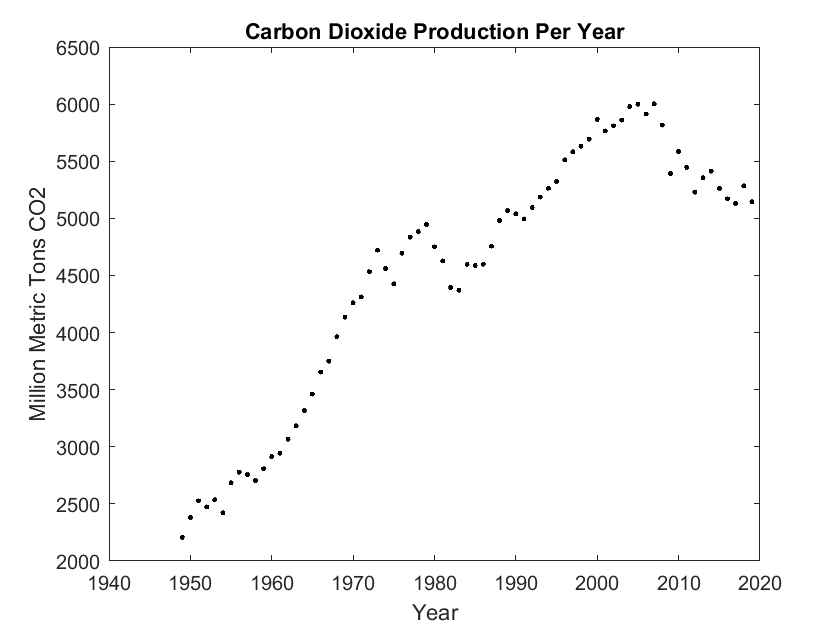

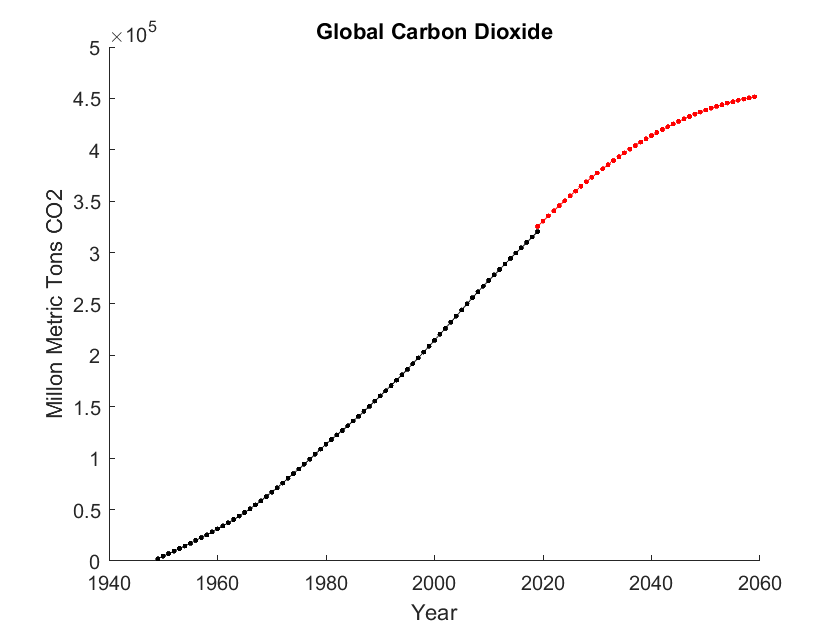

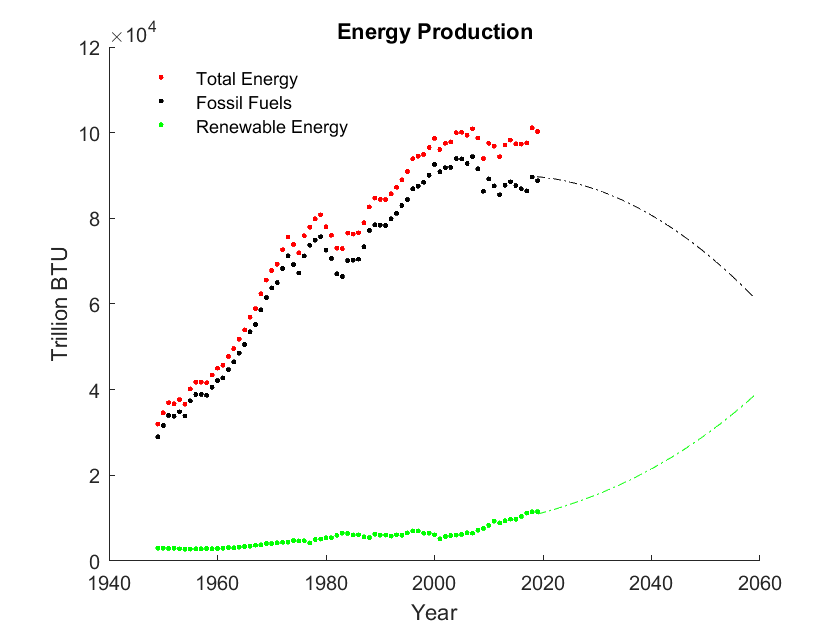

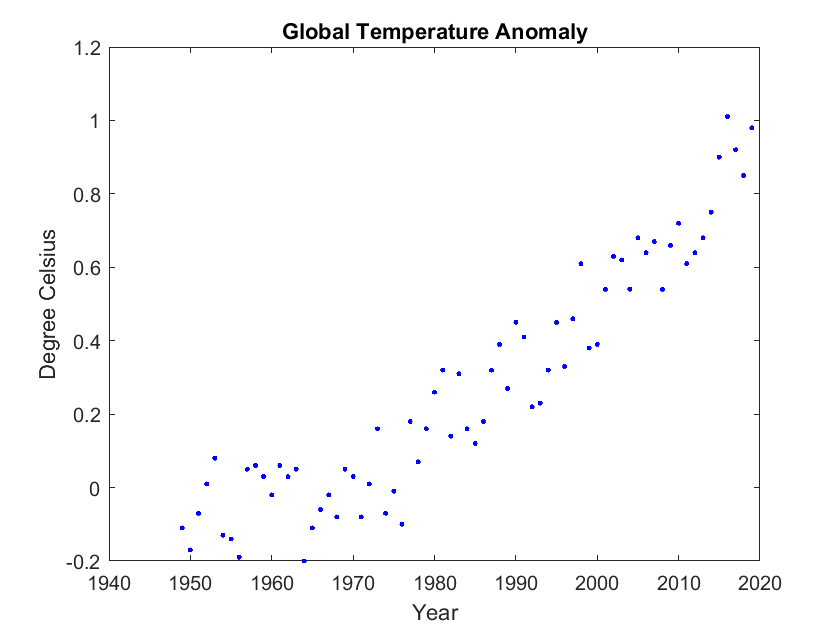

Year_ =40+ 2019;
Data_Visualizer(Year_);

[RenToTotal, FossToTotal] = EnergyRatio();
fprintf('%f%% of the energy is Fossil Fuels\n%f%% of the energy is Renewable',FossToTotal*100,RenToTotal*100);

92.571169% of the energy is Fossil Fuels
7.428831% of the energy is Renewable

[RenToTotal, FossToTotal] = EnergyRatio2019();
fprintf('%f%% of the energy in 2019 is Fossil Fuels\n%f%% of the energy in 2019 is Renewable',FossToTotal*100,RenToTotal*100);

88.522827% of the energy in 2019 is Fossil Fuels
11.477173% of the energy in 2019 is Renewable

#### Analysis

Based on the data, since 1949 there has been an upward trend with energy production globally with direct correlation to Carbon Dioxide output and global surface temperature. This is data has multiple dependencies like how CO2 measurments is based on the fossil fuels burned. Renewable energy only reduces the amount of CO2 released in the air, that is why the global levels is a cumulative sum since 1949. The energy production has been increasing but the fossil fuels and carbon output in the 2010's have been decreasing.

 In figure 3, the cumulative global CO2 shows from the prediction that the total amount of carbon will flatten out if renewable energy increases at the same rate. Since 1949 only 7% of our total energy was renewable while 93% of it was fossil fuels. In 2019 11.5% of the total energy was renewable while 88% was fossil fuels. This shows a inversely trend between the two productions, and only a sign that if we can produce as much renewable to keep up with the deduction of fossil fuels, the net zero initiative would be widespread globally.

### Scrubbing Code

function Data_Scrubber()
fclose('all');
clear
YEAR = 1949;
Consumption_scrub();
Electricity_scrub()
Renewable_scrub();
RegressionData();
fclose('all');

    function Consumption_scrub()
    save Data/CO2.csv
    save Data/CO2FULL.csv
    save Data/Energy.csv
    infile = fopen('Data/Consumption_Energy.csv','r'); %contains Total Energy consumption BTU & CO2 emissions gigatons
    outfileCO2 = fopen('Data/CO2.csv','w');
    outfileEnergy = fopen('Data/Energy.csv','w');
    if (infile ~= -1)
        aline = fgetl(infile);
        while (aline ~= -1)
            %"MSN","YYYYMM","Value","Column_Order","Description","Unit"
            linesplit = strsplit(aline,",");
            if (str2double(linesplit{4}) == 1 && str2double(linesplit{2}(1:end-2)) >= YEAR)
                fprintf(outfileEnergy,'%s,%.3f\n',linesplit{2}(1:end-2), str2double(linesplit{3})*1000);
            end
            if (str2double(linesplit{4}) == 8) && (str2double(linesplit{2}(1:end-2)) >= YEAR)
                fprintf(outfileCO2,'%s,%.3f\n', linesplit{2}(1:end-2), str2double(linesplit{3}));
            end
            aline = fgetl(infile);
        end
    end
    end

    function Electricity_scrub()
    save Data/Electricity.csv
    infile = fopen('Data/Electricity_Generation.csv','r'); %Contains Electricity in kWh
    outfileElectricity = fopen('Data/Electricity.csv','w');
    if (infile ~= -1)
        aline = fgetl(infile);
        while (aline ~= -1)
            %"MSN","YYYYMM","Value","Column_Order","Description","Unit"
            linesplit = strsplit(aline,",");
            if (str2double(linesplit{4}) == 4 && str2double(linesplit{2}(1:end-2)) >= YEAR)
                fprintf(outfileElectricity,'%s,%.3f\n',linesplit{2}(1:end-2), str2double(linesplit{3}));
            end
            aline = fgetl(infile);
        end
    end
    end

    function Renewable_scrub()
    save Data/RenewableGen.csv
    save Data/RenewableCon.csv
    infile = fopen('Data/Renewable_Energy.csv','r'); %Contains Renewable Energy Consumption and Generation in BTU
    outfileGen = fopen('Data/RenewableGen.csv','w');
    outfileCon = fopen('Data/RenewableCon.csv','w');
    if (infile ~= -1)
        aline = fgetl(infile);
        while (aline ~= -1)
            %"MSN","YYYYMM","Value","Column_Order","Description","Unit"
            linesplit = strsplit(aline,",");
            if (str2double(linesplit{2}(end-1:end)) == 13)
                if (str2double(linesplit{4}) == 4 && str2double(linesplit{2}(1:end-2)) >= YEAR)
                    fprintf(outfileGen,'%s,%.3f\n',linesplit{2}(1:end-2), str2double(linesplit{3}));
                end
                if (str2double(linesplit{4}) == 13 && str2double(linesplit{2}(1:end-2)) >= YEAR)
                    fprintf(outfileCon,'%s,%.3f\n',linesplit{2}(1:end-2), str2double(linesplit{3}));
                end
            end
            aline = fgetl(infile);
        end
    end
    end
    function RegressionData()
    save Data/RegData.csv
    RegData         =   fopen('Data/RegData.csv','w');
    TotalEnergy     =   textscan(fopen('Data/Energy.csv','r'),'%d,%f');
    RenewableEnergy =   textscan(fopen('Data/RenewableGen.csv','r'),'%d,%f');
    CO2             =   textscan(fopen('Data/CO2.csv','r'),'%d,%f');
    GlobalTemps     =   textscan(fopen('Data/Global_Temps.csv','r'),'%d,%f,%f');
    counter = 1;
    %Year,Total Energy, Non Renewable Energy, Renewable Energy, CO2, Global Temps
    while (counter < 2020 -  YEAR+1)
        fprintf(RegData,'%d,%f,%f,%f,%f,%f\n',YEAR - 1 + counter,TotalEnergy{2}(counter),TotalEnergy{2}(counter)-RenewableEnergy{2}(counter),RenewableEnergy{2}(counter),CO2{2}(counter),GlobalTemps{2}(counter));
        counter = counter + 1;
    end
    end
end
function [RenToTotal, FossToTotal] = EnergyRatio()
TotalEnergy     =   textscan(fopen('Data/Energy.csv','r'),'%d,%f');
RenewableEnergy =   textscan(fopen('Data/RenewableGen.csv','r'),'%d,%f');

RenToTotal =  sum(RenewableEnergy{2}(:))/sum(TotalEnergy{2}(:));
FossToTotal = (sum(TotalEnergy{2}(:)) - sum(RenewableEnergy{2}(:)))/sum(TotalEnergy{2}(:));
end
function [RenToTotal, FossToTotal] = EnergyRatio2019()
TotalEnergy     =   textscan(fopen('Data/Energy.csv','r'),'%d,%f');
RenewableEnergy =   textscan(fopen('Data/RenewableGen.csv','r'),'%d,%f');

RenToTotal =  RenewableEnergy{2}(end)/TotalEnergy{2}(end);
FossToTotal = (TotalEnergy{2}(end)- RenewableEnergy{2}(end))/TotalEnergy{2}(end);
end

### Visuals Code

function Data_Visualizer(Year_)
%Year,Total Energy, Non Renewable Energy, Renewable Energy, CO2, Global Temps
RegData = fscanf(fopen('Data/RegData.csv'),'%d,%f,%f,%f,%f,%f\n',[6,inf])';
cla
figure(1)
plotEnergy();
figure(2)
plotCO2();
figure(4)
plotTemperature();
fclose('all');

    function plotEnergy()
        hold on
        plot(RegData(:,1),RegData(:,2),'r.');
        plot(RegData(:,1),RegData(:,3),'k.');
        plot(RegData(:,1),RegData(:,4),'g.');
        hold off
        xlabel('Year');
        ylabel('Trillion BTU');
        title('Energy Production');
    end

    function plotTemperature()
        plot(RegData(:,1),RegData(:,6),'b.');
        xlabel('Year');
        ylabel('Degree Celsius');
        title('Global Temperature Anomaly');
    end

    function plotCO2()
        plot(RegData(:,1),RegData(:,5),'k.');
        xlabel('Year');
        ylabel('Million Metric Tons CO2');
        title('Carbon Dioxide Production Per Year');
        figure(3);
        hold on
        plot(RegData(:,1),cumsum(RegData(:,5)),'k.-');
        xlabel('Year');
        ylabel('Millon Metric Tons CO2');
        title('Global Carbon Dioxide');
        [trainedModel, validationRMSE] = RegressionModel(RegData);
        coeffsTE = polyfit(1949:2019,RegData(:,3),2);
        coeffsRE = polyfit(1949:2019,RegData(:,4),3);
        Y = 2019:Year_;
        FE = polyval(coeffsTE,Y);
        RE = polyval(coeffsRE,Y);
        FutureCO2 = trainedModel.predictFcn([Y', FE', RE']);
        Offset = sum(RegData(:,5));
        plot(Y,cumsum(FutureCO2) + Offset,'r.--');
        hold off
        figure(1)
        hold on
        plot(Y,FE,'k-.',Y,RE,'g-.');
        legend('Total Energy','Fossil Fuels','Renewable Energy','Location','northwest')
        hold off
    end
end


#### Regression Function


function [trainedModel, validationRMSE] = RegressionModel(trainingData)
% [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% Returns a trained regression model and its RMSE. This code recreates the
% model trained in Regression Learner app. Use the generated code to
% automate training the same model with new data, or to learn how to
% programmatically train models.
%
%  Input:
%      trainingData: A matrix with the same number of columns and data type
%       as the matrix imported into the app.
%
%  Output:
%      trainedModel: A struct containing the trained regression model. The
%       struct contains various fields with information about the trained
%       model.
%
%      trainedModel.predictFcn: A function to make predictions on new data.
%
%      validationRMSE: A double containing the RMSE. In the app, the
%       History list displays the RMSE for each model.
%
% Use the code to train the model with new data. To retrain your model,
% call the function from the command line with your original data or new
% data as the input argument trainingData.
%
% For example, to retrain a regression model trained with the original data
% set T, enter:
%   [trainedModel, validationRMSE] = trainRegressionModel(T)
%
% To make predictions with the returned 'trainedModel' on new data T2, use
%   yfit = trainedModel.predictFcn(T2)
%
% T2 must be a matrix containing only the predictor columns used for
% training. For details, enter:
%   trainedModel.HowToPredict

% Auto-generated by MATLAB on 08-Dec-2020 15:09:48


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6'});

predictorNames = {'column_1', 'column_3', 'column_4'};
predictors = inputTable(:, predictorNames);
response = inputTable.column_5;
isCategoricalPredictor = [false, false, false];

% Train a regression model
% This code specifies all the model options and trains the model.
regressionGP = fitrgp(...
    predictors, ...
    response, ...
    'BasisFunction', 'none', ...
    'KernelFunction', 'ardmatern52', ...
    'Sigma', 10921.89943055265, ...
    'Standardize', true);

% Create the result struct with predict function
predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
gpPredictFcn = @(x) predict(regressionGP, x);
trainedModel.predictFcn = @(x) gpPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedModel.RegressionGP = regressionGP;
trainedModel.About = 'This struct is a trained model exported from Regression Learner R2020a.';
trainedModel.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 3 columns because this model was trained using 3 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6'});

predictorNames = {'column_1', 'column_3', 'column_4'};
predictors = inputTable(:, predictorNames);
response = inputTable.column_5;
isCategoricalPredictor = [false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedModel.RegressionGP, 'KFold', 5);

% Compute validation predictions
validationPredictions = kfoldPredict(partitionedModel);

% Compute validation RMSE
validationRMSE = sqrt(kfoldLoss(partitionedModel, 'LossFun', 'mse'));
end